clear; clc; close all;

%% 1. KONSTANTEN & PARAMETER
% AEB Parameter
v_min = 20 / 3.6;        % System aktiv ab 20 km/h
v_max = 60 / 3.6;        % System aktiv bis 60 km/h
bremskraft_min = 5.0;    % Vollbremsung mit 5 m/s²
ttc_warnung = 2.0;       % FCW Warnung bei 2.0s
ttc_bremse = 1.2;        % AEB Eingriff bei 1.2s

% Fahrer-Übersteuerung (Override) Schwellwerte
SCHWELLE_LENKUNG = 15;   % Grad (Absolutwert)
SCHWELLE_GAS = 10;       % Gaspedalstellung in %

% Simulations-Parameter
time_step = 0.01;
gesamtzeit = 15;
zeit = 0:time_step:gesamtzeit;

% Fußgänger (Pedestrian)
v_pedestrian = 5 / 3.6;  % 5 km/h
pedestrian_x = 35;       % 35m vor dem Auto
pedestrian_y = -3;       % Startet 3m rechts/links der Fahrbahn

% Auto Initialisierung
auto_x = 0;
auto_y = 0;
v_ego = 50 / 3.6;        % 50 km/h Startgeschwindigkeit

%% 2. DATEN-ARRAYS INITIALISIEREN
auto_position_x = zeros(size(zeit));
auto_position_y = zeros(size(zeit));
auto_geschwindigkeit = zeros(size(zeit));

pedestrian_position_x = zeros(size(zeit));
pedestrian_position_y = zeros(size(zeit));

ttc_werte = zeros(size(zeit));
warnung_aktiv = false(size(zeit));
bremse_aktiv = false(size(zeit));
bremskraft = zeros(size(zeit));
driver_override_aktiv = false(size(zeit)); % Zum Speichern, wann Fahrer eingreift

% --- FAHREREINGABEN (Simulation) ---
% Hier simulieren wir Lenkung und Gas. 
% Standardmäßig sind diese 0 (Fahrer macht nichts).
lenkrad_winkel = zeros(size(zeit)); 
gaspedal_pos = zeros(size(zeit));

% >>> TEST-SZENARIO (Optional: Hier Kommentar entfernen um Override zu testen) <<<
% Beispiel: Fahrer lenkt bei Sekunde 1.5 stark ein -> AEB sollte abbrechen
% lenkrad_winkel(zeit > 1.5 & zeit < 3.0) = 20; 

%% 3. INITIALISIERUNG STARTWERTE
auto_position_x(1) = auto_x;
auto_position_y(1) = auto_y;
auto_geschwindigkeit(1) = v_ego;

pedestrian_position_x(1) = pedestrian_x;
pedestrian_position_y(1) = pedestrian_y;

ttc_werte(1) = Inf;

%% 4. HAUPTSIMULATIONSSCHLEIFE
for i = 2:length(zeit)
    
    % --- A. PHYSIK & BEWEGUNG ---
    v_aktuell = auto_geschwindigkeit(i-1);
    
    % Auto Bewegung
    auto_position_x(i) = auto_position_x(i-1) + (v_aktuell * time_step);
    auto_position_y(i) = 0; 
    
    % Fußgänger Bewegung (nur Y-Richtung)
    pedestrian_position_x(i) = pedestrian_x; 
    pedestrian_position_y(i) = pedestrian_position_y(i-1) + (v_pedestrian * time_step);
    
    
    % --- B. SENSORIK & LOGIK ---
    
    % 1. TTC Berechnung
    ttc_werte(i) = berechne_ttc(auto_position_x(i), v_aktuell, pedestrian_position_x(i), pedestrian_position_y(i));
    
    % 2. Systemverfügbarkeit prüfen (Geschwindigkeit)
    system_aktiv = pruefe_geschwindigkeitsbereich(v_aktuell, v_min, v_max);
    
    % 3. Fahrer-Übersteuerung prüfen (NEU!)
    % Wenn Lenkung > Schwelle ODER Gas > Schwelle -> Override = true
    is_steering = abs(lenkrad_winkel(i)) > SCHWELLE_LENKUNG;
    is_gas = gaspedal_pos(i) > SCHWELLE_GAS;
    
    driver_override = is_steering || is_gas;
    driver_override_aktiv(i) = driver_override; % Speichern für Plot
    
    % Wenn System inaktiv (zu langsam/schnell), Werte vom Vor-Schritt übernehmen & Loop fortsetzen
    if ~system_aktiv
      warnung_aktiv(i) = warnung_aktiv(i-1);
      bremse_aktiv(i) = bremse_aktiv(i-1);
      bremskraft(i) = bremskraft(i-1);
      auto_geschwindigkeit(i) = v_aktuell;
      continue;
    end

    % 4. Kollisionswarnung (FCW)
    % Warnung bleibt auch bei Override aktiv (Fahrer soll ja gewarnt werden),
    % nur die Bremsung wird unterdrückt.
    warnung_alt_input = warnung_aktiv(i-1);
    warnung_aktiv(i) = kollisionswarnung(warnung_alt_input, ttc_werte(i), ttc_warnung);
    
    % Optional: Konsolenausgabe für Warnung
    if warnung_aktiv(i) && ~warnung_alt_input
        fprintf('Zeit %.2fs: FCW WARNUNG (Optisch + Akustisch)\n', zeit(i));
    end
    
    % 5. Notbremsung (AEB)
    % Hier übergeben wir jetzt "driver_override" an die Funktion!
    bremse_alt_input = bremse_aktiv(i-1);
    kraft_alt_input  = bremskraft(i-1);
    
    [bremse_aktiv(i), bremskraft(i)] = notbremsung(bremse_alt_input, kraft_alt_input, ...
                                                   ttc_werte(i), ttc_bremse, ...
                                                   bremskraft_min, driver_override);
    
    % --- C. FAHRZEUGREAKTION ---
    
    % Geschwindigkeit update
    if bremse_aktiv(i)
        neue_v = v_aktuell - (bremskraft(i) * time_step);
    else
        neue_v = v_aktuell;
    end
    
    if neue_v < 0; neue_v = 0; end % Kein Rückwärtsfahren
    auto_geschwindigkeit(i) = neue_v;
end

Zeit 0.73s: FCW WARNUNG (Optisch + Akustisch)


ACHTUNG: Notbremsung eingeleitet (TTC=1.20s)



%% 5. HILFSFUNKTIONEN

function [system_aktiv] = pruefe_geschwindigkeitsbereich(v, v_min, v_max)
    system_aktiv = (v >= v_min && v <= v_max);
end

function [ttc] = berechne_ttc(auto_x, auto_v, ped_x, ped_y)
    dx = ped_x - auto_x;
    dy = abs(ped_y); 
    
    % Kollisionsgefahr nur wenn Fußgänger relevant (dy < 2m) und Auto vor dem Fußgänger
    if dy < 2.0 && dx > 0
        if auto_v > 0
            ttc = dx / auto_v;
        else
            ttc = Inf;
        end
    else
        ttc = Inf;
    end
end

function [warnung_neu] = kollisionswarnung(warnung_alt, ttc, ttc_warnung)
    % Hysterese Logik für Warnung
    if ttc <= ttc_warnung && ~warnung_alt
        warnung_neu = true;
    elseif ttc > ttc_warnung + 0.5
        warnung_neu = false;
    else
        warnung_neu = warnung_alt;
    end
end

% --- UPDATED NOTBREMSUNG MIT OVERRIDE ---
function [bremse_neu, bremskraft_neu] = notbremsung(bremse_alt, bremskraft_alt, ttc, ttc_bremse, bremskraft_min, override)
    
    % Wenn der Fahrer eingreift, wird Bremsung SOFORT deaktiviert/verhindert
    if override
        if bremse_alt
            fprintf('INFO: Notbremsung durch Fahrer abgebrochen!\n');
        end
        bremse_neu = false;
        bremskraft_neu = 0;
        return; % Funktion hier beenden
    end

    % Normale AEB Logik
    if ttc <= ttc_bremse && ~bremse_alt
        bremse_neu = true;
        bremskraft_neu = bremskraft_min;
        fprintf('ACHTUNG: Notbremsung eingeleitet (TTC=%.2fs)\n', ttc);
    elseif bremse_alt && ttc > ttc_bremse + 0.5
        bremse_neu = false;
        bremskraft_neu = 0; 
    else
        bremse_neu = bremse_alt;
        bremskraft_neu = bremskraft_alt;
    end
end

    %% 6. VISUALISIERUNG (Optimiert: 2 Fenster)
fprintf('\nSimulation abgeschlossen. Erstelle Plots...\n');


Simulation abgeschlossen. Erstelle Plots...


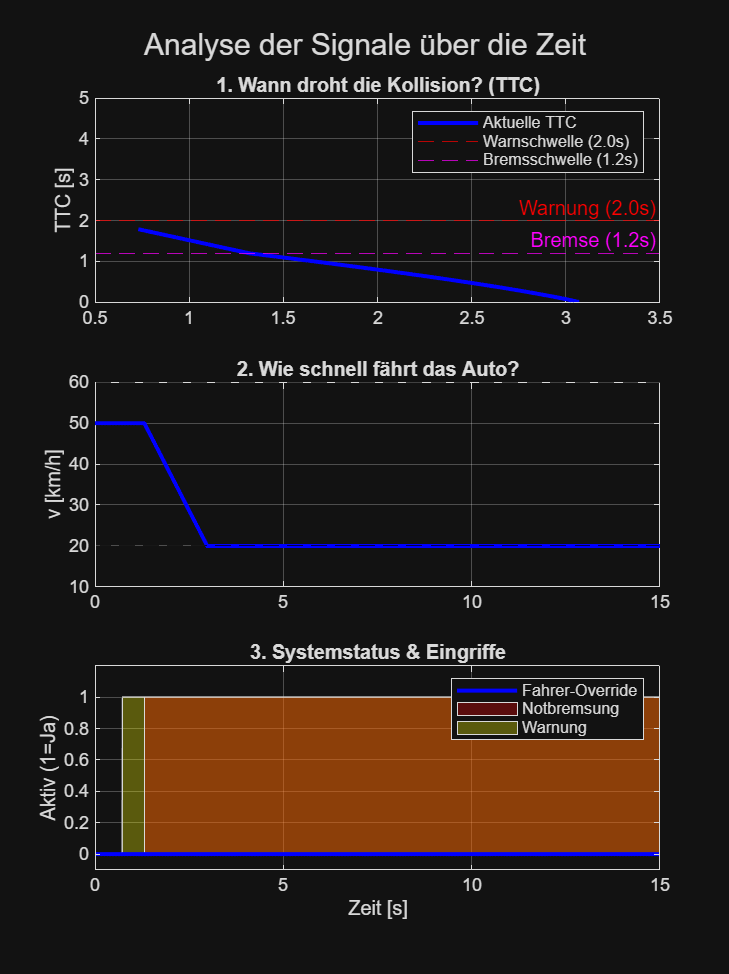


% --- FENSTER 1: ZEITDATEN (Zur Analyse) ---
figure('Name', 'AEB Analyse - Zeitdaten', 'Position', [50 50 600 800]);
sgtitle('Analyse der Signale über die Zeit');

% Plot 1: TTC (Ganz oben)
subplot(3,1,1); % 3 Zeilen, 1 Spalte, Bild 1
plot(zeit, ttc_werte, 'b', 'LineWidth', 2); hold on;
yline(ttc_warnung, 'r--', 'Warnung (2.0s)');
yline(ttc_bremse, 'm--', 'Bremse (1.2s)');
ylim([0 5]); grid on;
ylabel('TTC [s]'); title('1. Wann droht die Kollision? (TTC)');
legend('Aktuelle TTC', 'Warnschwelle (2.0s)', 'Bremsschwelle (1.2s)', 'Location', 'northeast');

% Plot 2: Geschwindigkeit (Mitte)
subplot(3,1,2); % Bild 2
plot(zeit, auto_geschwindigkeit*3.6, 'b', 'LineWidth', 2); hold on;
yline(v_min*3.6, 'k--'); yline(v_max*3.6, 'k--');
grid on;
ylabel('v [km/h]'); title('2. Wie schnell fährt das Auto?');

% Plot 3: Status (Unten - synchron zu oben)
subplot(3,1,3); % Bild 3
area(zeit, warnung_aktiv, 'FaceColor', 'y', 'FaceAlpha', 0.3); hold on; % Gelb hinterlegt
area(zeit, bremse_aktiv, 'FaceColor', 'r', 'FaceAlpha', 0.3);       % Rot hinterlegt
plot(zeit, driver_override_aktiv, 'b', 'LineWidth', 2);             % Schwarze Linie
ylim([-0.1 1.2]); grid on;
ylabel('Aktiv (1=Ja)'); xlabel('Zeit [s]');
title('3. Systemstatus & Eingriffe');
legend('Warnung', 'Notbremsung', 'Fahrer-Override', 'Location', 'northeast');

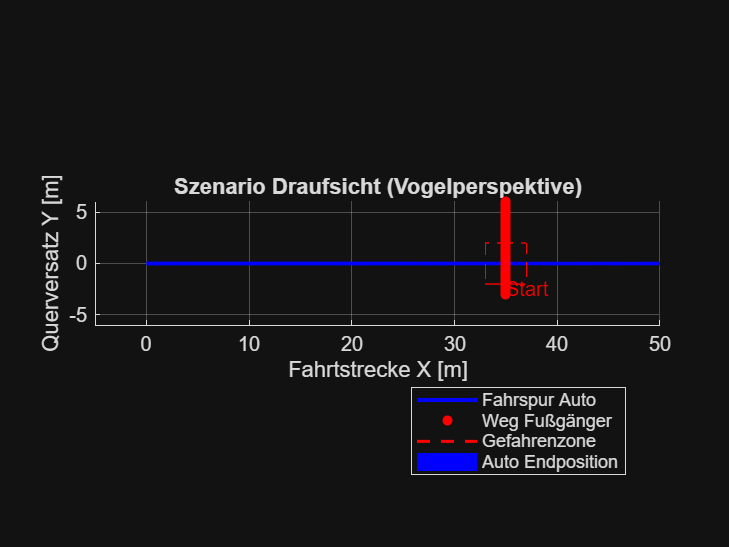



% --- FENSTER 2: SZENARIO (Große Ansicht) ---
figure('Name', 'AEB Szenario - Trajektorie', 'Position', [660 50 800 600]);

hold on; grid on; axis equal;

% 1. Auto Fahrspur zeichnen & Handle speichern (h1)
h1 = plot(auto_position_x, auto_position_y, 'b-', 'LineWidth', 2);

% 2. Fußgänger Weg zeichnen & Handle speichern (h2)
h2 = plot(pedestrian_position_x, pedestrian_position_y, 'r.', 'MarkerSize', 15);

% Fußgänger Start-Text
text(pedestrian_position_x(1), pedestrian_position_y(1)+0.5, 'Start', 'Color', 'r');

% 3. Gefahrenzone (Rechteck)
rectangle('Position', [pedestrian_x-2, -2, 4, 4], 'EdgeColor', 'r', 'LineStyle', '--');
% TRICK: Unsichtbare Linie für die Legende (h3)
h3 = plot(NaN, NaN, 'r--', 'LineWidth', 1.5); 

% 4. Auto Endposition (Rechteck)
last_x = auto_position_x(end);
rectangle('Position', [last_x-4, -1, 4, 2], 'FaceColor', 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b');
% TRICK: Unsichtbare Linie für die Legende (h4)
h4 = plot(NaN, NaN, 'b-', 'LineWidth', 10, 'Color', [0 0 1 0.2]); % Dicke transparente Linie simuliert Füllung

% Achsen beschriften
xlabel('Fahrtstrecke X [m]'); 
ylabel('Querversatz Y [m]');
title('Szenario Draufsicht (Vogelperspektive)');

% Zoom einstellen
xlim([-5 50]); 
ylim([-6 6]);

% JETZT: Legende explizit nur für h1, h2, h3, h4 erstellen
legend([h1, h2, h3, h4], ...
       'Fahrspur Auto', ...
       'Weg Fußgänger', ...
       'Gefahrenzone', ...
       'Auto Endposition', ...
       'Location', 'best');